Спектральная плотность прямоугольного импульса:


$$X_T \left(f\right)=\int_{-\frac{T}{2}}^{\frac{T}{2}} E\cdot e^{-j2\pi \mathrm{ft}} \mathrm{dt}=-\frac{E}{2\pi f}\cdot e^{-j2\pi \mathrm{ft}} {\left|\right.}_{-\frac{T}{2}}^{\frac{T}{2}} =-\frac{E}{j2\pi f}\left(e^{-j\frac{2\pi \mathrm{fT}}{2}} -e^{j\frac{2\pi \mathrm{fT}}{2}} \right)=\frac{E}{\pi f}\mathrm{sin}\left(\pi f\;T\right)=E\;T\frac{\mathrm{sin}\left(\pi fT\right)}{\pi fT}$$


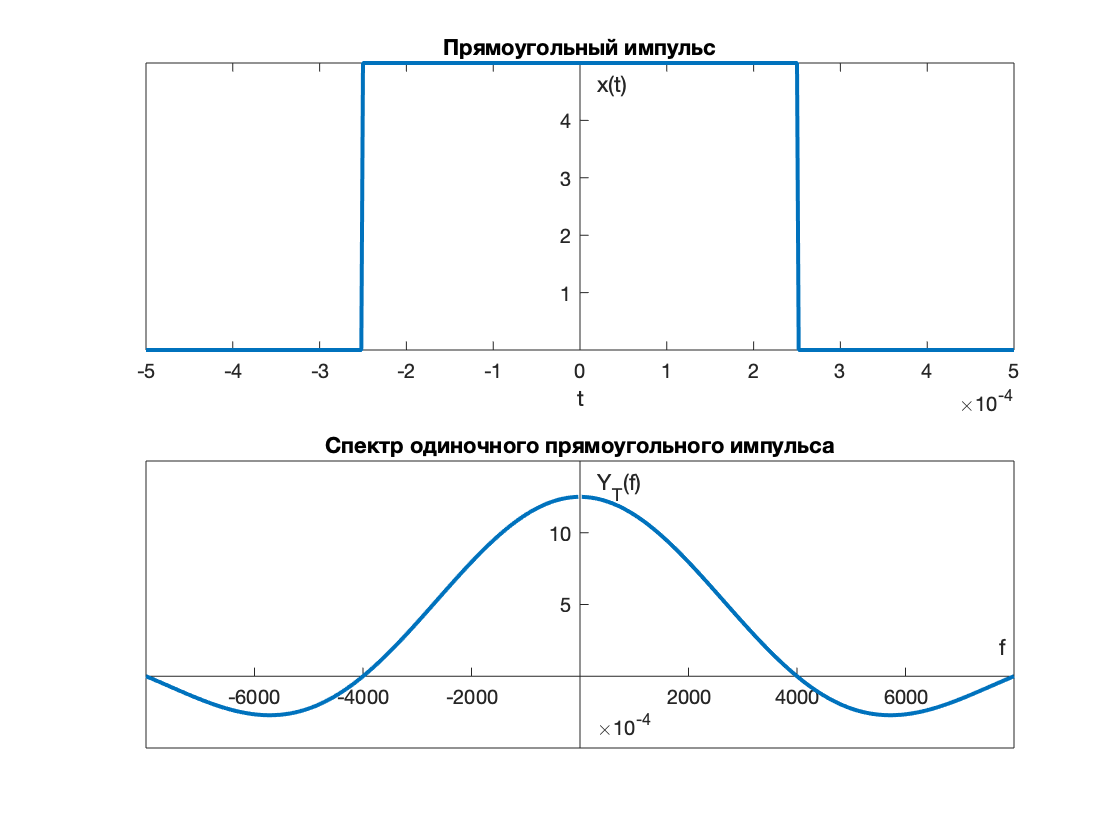

     
tau=1./(2*10^3); 
f0=1/tau; 
E=5;
f=linspace(-4*f0, 4*f0, 513);
t=linspace(-tau, tau, 513); 
xt=E.*[zeros(1,(numel(t)-1)/4), ones(1,((numel(t))-1)/2+1), zeros(1,(numel(t)-1)/4)];
XTf=E.*tau.*sin(pi.*tau.*f)./(pi.*f.*tau);
% Строим графики
figure;
subplot1 = subplot(2,1,1); plot(t, xt,'LineWidth',2);
set(subplot1,'XAxisLocation','origin','YAxisLocation','origin');
xlabel('t'); ylabel('x(t)'); title('Прямоугольный импульс');
subplot3 = subplot(2,1,2); plot(f, XTf, 'LineWidth', 2);
set(subplot3,'XAxisLocation','origin','YAxisLocation','origin');
xlabel('f'); ylabel('Y_T(f)'); title('Спектр одиночного прямоугольного импульса');

Разность между центральным пиком и ближайшим боковым: 0,05 - (-0,0108) = 0,0608